% %%12/03/2020
% %Author: Juan A. Vasquez Peralvo
% % City: Madrid -Spain
% %This code allows to generate a surface based on the phase variation of the
% %elements described by a .mat file
% %This code is free of use with the condition of cite this work.
% %Enjoy!!!!

## Matlab Section

% 
% 
% clear all
% close all
% clc
% %Import the values of the unit cell phase variation
% load('./Data.mat');
% 

### Initial parameters

% 
% 
% frequency=10; %%Operational frequency
% N=5; % Number of Unit cell for each row
% p=10; % Period of the unit cell
% g_phase=rand(N,N)*288.8; % Randmo phase elements 
% epsilon=3.55; % Permittivity of the unit cell
% metal_thickness=0.035; %Thikness of the metal 
% substrate_thickness=2.2;  %Thickness of the substrate
% k=1; %This variable is placed in case we need an iterative process.
% %%%%

### 2D phase graph

% 
% xhex=[ -p/2 p/2 p/2 -p/2]; % x-coordinates of the vertices
% yhex=[-p/2 -p/2 p/2 p/2]; % y-coordinates of the vertices
% 
% 
% for i=0:N-1 %CRow control
%        for j=0:N-1 %Columns control
%           
%            xi=-((N-1)/2-i)*p;
%            yi=((N-1)/2-j)*p;
%            g_adapted(i+1,j+1)=interp1(S11_phase,g,g_phase(i+1,j+1),'linear','extrap');% extrapolate to obtain the size of the inner patch
%             patch(xhex-xi,yhex+yi,g_phase(i+1,j+1)); % make a hexagon at [2i,2j]
%        end
%     end
%     
%     axis equal
%     axis off
%     colormap(fire)
%     colorbar
%     pause(2)
% 
%     

## CST Section

% 
% 
% %%Start CST package
% CST = CST_MicrowaveStudio(cd,'./CST/Full_structure_1.CST'); %% Name and path of the CST FILE
% CST.setUpdateStatus(false) %% Saving time
% 
% tStart = tic;
% %%%
% %%%% CST variables
%  CST.addParameter('Er',epsilon);
%  CST.addParameter('Mue',1);
%  CST.addParameter('tand',0.002);
%  CST.addParameter('Fmin',0.1);
%  CST.addParameter('Fmax',15);
% %%%%%
% %%%% Materials definitions
% CST.addNormalMaterial('RO4003','Er','Mue','tand',[0 0 1]);
% CST.addNormalMaterial('Material_0',1,1,0,[0 0 1]);
% %%%%
% %%%% Frequency range of simulation
% CST.setFreq(0.1,11)
% 
% %%%%
% %%% Monitor definitions
% CST.addFieldMonitor('farfield',frequency);
% 
% %%%
% %Symmetry planes
% %CST.addSymmetryPlane('X','electric')
% %CST.addSymmetryPlane('Y','magnetic')
% 
%  CST.addBrick( [-p*N/2 p*N/2], [-p*N/2 p*N/2], [0 metal_thickness],'GND','Component1','PEC'); %% Global GND
%  CST.addBrick( [-p*N/2 p*N/2], [-p*N/2 p*N/2], [metal_thickness metal_thickness+substrate_thickness],'Substrate','Component1','RO4003'); %% Global Substrate
% a=1; % to identify the block in CST
% for i=0:N-1
%    for j=0:N-1
%        a=a+1;
%        Xi=-((N-1)/2-i)*p;
%        Yi=((N-1)/2-j)*p;
%        
%         CST.addBrick( [-((N-1)/2-i)*(p)-(g_adapted(i+1,j+1)/2) -((N-1)/2-i)*(p)+(g_adapted(i+1,j+1)/2)],...
%             [-((N-1)/2-j)*(p)-(g_adapted(i+1,j+1)/2) -((N-1)/2-j)*(p)+(g_adapted(i+1,j+1)/2)],...
%             [metal_thickness+substrate_thickness 2*metal_thickness+substrate_thickness],sprintf('Brickk%d', a),'Component1','PEC');
%         % CST.addBrick( [-((N-1)/2+0.5-i)*p -((N-1)/2+0.5-i-1)*p],...
%           %   [-((N-1)/2+0.5-j)*p -((N-1)/2+0.5-j-1)*p],[e t-1*e],...
%            %  sprintf('Brick%d', a),'Component1','Material_1');
%         %CST.translateObject(sprintf('Component1:Brickk%d',a),0,0,t-e,1,'destination','Component1') %% Desplazamos y copiamos los rectangulos
% %         CST.intersectObjects(sprintf('Component1:Brickk%d',a),sprintf('Component1:Brick%d',a))%% Sustraemos el hexagon inerno del externo
% 
% 
%    end
% end
% 
% 
%  
% CST.addPlaneWave(); %% This function was created by me, so if you need to modify anything from this you will need to do it in the CST_MicrowaveStudio.m file
% 
% CST.acceleration();  %% This function was created by me, so if you need to modify anything from this you will need to do it in the CST_MicrowaveStudio.m file
% 
%  CST.addToHistory; %%Linked to the CST.setUpdateStatus(false) line
%  CST.save();
%  CST.runSimulation;


# Processing the simulated data

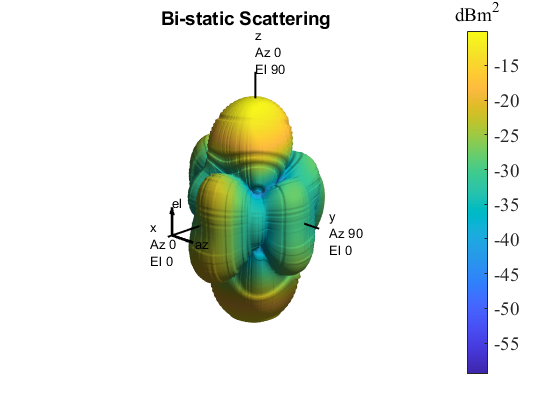

%% Retrieve the Farfield and plot
theta = 0:2:180;
phi = 0:2:360;
az=-180:2:180;
el=-90:2:90;


%[Eabs] = CST.getFarField(frequency,theta,phi,'units','directivity','ffid','farfield (f=10) [pw]');
phaseEabs=zeros(size(Eabs));
freqVector  = [10 11].*1e9;        % Frequency range for element pattern
antenna     = phased.CustomAntennaElement('PatternCoordinateSystem','phi-theta',...
                              'PhiAngles',phi,...
                              'ThetaAngles',theta,...
                              'MagnitudePattern', Eabs,...
                              'PhasePattern',phaseEabs);
                           
                          

fc=10e9;
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes1 = axes('Parent',figure1);
axis off
hold(axes1,'on');
pattern(antenna,fc,'Type','powerdb','Normalize', false)
hcb=colorbar(axes1,'FontSize',14,'FontName','Times New Roman');
hcb.Title.String="dBm^2";
title('Bi-static Scattering','FontName','TimesNewRoman','FontSize',14);




newax = rotx(90)*roty(90);
Eabs_r=rotpat(Eabs,az,el,newax);
antenna_r     = phased.CustomAntennaElement('PatternCoordinateSystem','phi-theta',...
                              'PhiAngles',phi,...
                              'ThetaAngles',theta,...
                              'MagnitudePattern', Eabs_r,...
                              'PhasePattern',phaseEabs);
newax = rotx(0)*roty(90);
Eabs_r2=rotpat(Eabs,az,el,newax);
antenna_r2     = phased.CustomAntennaElement('PatternCoordinateSystem','phi-theta',...
                              'PhiAngles',phi,...
                              'ThetaAngles',theta,...
                              'MagnitudePattern', Eabs_r2,...
                              'PhasePattern',phaseEabs);

%pattern(antenna_r2,fc,'Type','powerdb','Normalize', false)
%figure                        

## Plot in uv plane

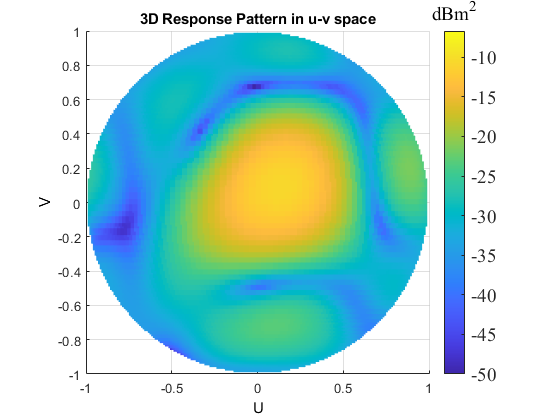

% figure2=figure;
figure2=figure;
 axes1 = axes('Parent',figure2);
hold(axes1,'on');

pattern(antenna_r,fc,[-1:.01:1],[-1:.01:1],'CoordinateSystem','uv','Type','powerdb','Normalize', false)
% grid(axes1,'on');
% axis(axes1,'square');
% hold(axes1,'off');
 hcb=colorbar(axes1,'FontSize',14,'FontName','Times New Roman');
 hcb.Title.String="dBm^2";


figure

## XY plane plot

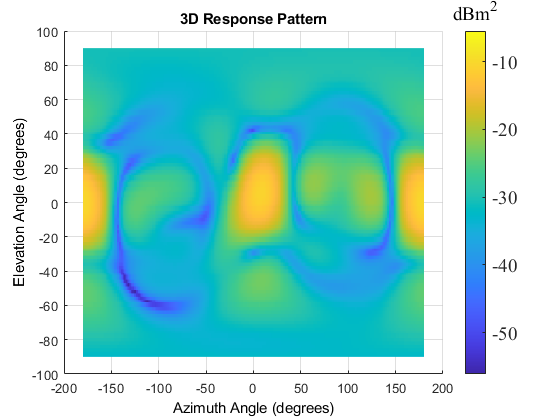

figure2=figure;
 axes1 = axes('Parent',figure2);
hold(axes1,'on');
pattern(antenna_r,fc,'coordinatesystem','rectangular','Type','powerdb','Normalize', false)
view(2)
 hcb=colorbar(axes1,'FontSize',14,'FontName','Times New Roman');
 hcb.Title.String="dBm^2";

 figure

## Plot cuts

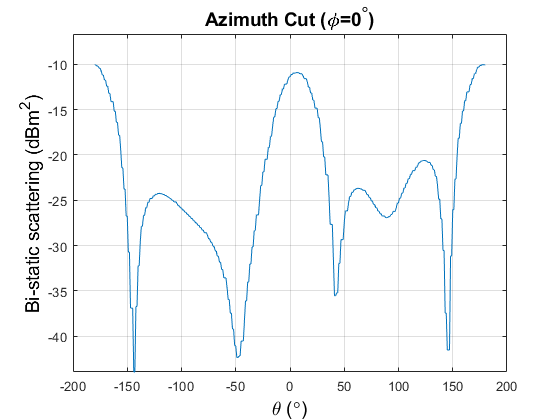

pattern(antenna_r,fc,-180:180,0,'coordinatesystem','rectangular','Type','powerdb','Normalize', false)
title('Azimuth Cut (\phi=0^\circ)','FontName','TimesNewRoman','FontSize',14);
xlabel('\theta (\circ)','FontName','TimesNewRoman','FontSize',14);
ylabel('Bi-static scattering (dBm^2)','FontName','TimesNewRoman','FontSize',14);

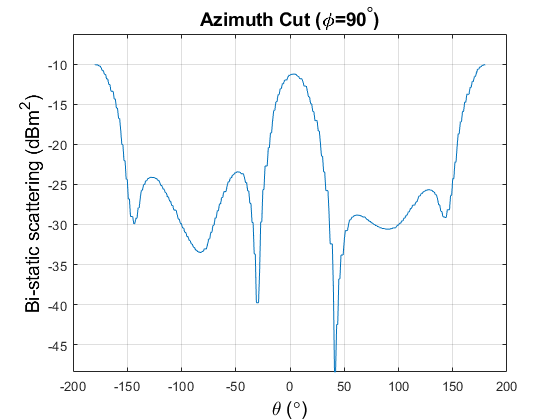


figure
% %CST.closeProject();
% save('results.mat','Results')

pattern(antenna_r2,fc,-180:180,0,'coordinatesystem','rectangular','Type','powerdb','Normalize', false)
title('Azimuth Cut (\phi=90^\circ)','FontName','TimesNewRoman','FontSize',14);
xlabel('\theta (\circ)','FontName','TimesNewRoman','FontSize',14);
ylabel('Bi-static scattering (dBm^2)','FontName','TimesNewRoman','FontSize',14);